# Monte-carlo estimation of error in D region power spectra

## Summary

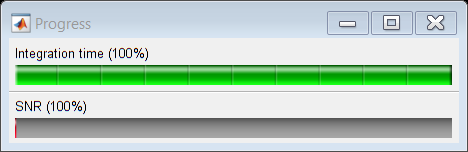

clear all;
iTime = 1:10;
integrationTimeArray =linspace(500,5000,length(iTime));
iSNR = 1:10;
SNRArray = linspace(0.1,2,length(iSNR)); 
ifWidth = 1:10;
fWidthArray = linspace(1,100,length(ifWidth));
mean_dist=@(dist) mean(real(dist(:)));
std_dist=@(dist) std(real(dist(:)));
multiWaitbar('CLOSEALL');
multiWaitbar('Integration time',0);
multiWaitbar('SNR',0);
% multiWaitbar('Spectral width',0);
tic
for t=iTime
    multiWaitbar('Integration time','increment',1/iTime(end),'color','g');
    for s=iSNR
    multiWaitbar('SNR','increment',1/iSNR(end));
        for fw=ifWidth
%         multiWaitbar('Spectral width','increment',1/ifWidth(end));
%         tic
        % Controllable Inputs
        nExperiments = 2^8;
        integrationTime = integrationTimeArray(t); % ms
        
        % ACF Characteristics
        SNR = SNRArray(s);
%         altitude = 60; %km 
        
        noisePower = 100;
        signalPower = SNR*noisePower;
        fWidth = fWidthArray(fw); % in Hz
        dopplerFrequency = 10; %in Hz
        
        
        
        % Pulse characteristics
        IPP = 2; %in ms
        if IPP ==0
            nyquistSamplingRate = 10*2*fWidth; % n times the nyquist frequency
        elseif (IPP*10^-3<(1/2*fWidth)) % if IPP is less than nyquist sampling time
            nyquistSamplingRate=1/(IPP*10^-3);
        else
            warning('IPP is longer than 1/(2*fWidth) - the signal is being undersampled');
        end
        
        maxLag = 4*(1/fWidth); % n times the decorrelation time scale
        
        % Sampling
        sampleTime = 1/nyquistSamplingRate; %IPP
        nSamples = 2^nextpow2(maxLag/sampleTime);
        nPulseTrains = ceil(integrationTime/(nSamples*sampleTime*10^3)); 
        
        
%         display(['Sample Time/ IPP: ',num2str(sampleTime*10^3,4),' ms']);
%         display(['Decorrelation Time: ',num2str((1/fWidth).*10^3,4),' ms']);
%         display(['Max Lag: ',num2str(nSamples*sampleTime*10^3,4),' ms']);
%         display(['nSamples: ',num2str(nSamples)]);
%         display(['Experiments #: ',num2str(nExperiments),' Pulse trains #: ',num2str(nPulseTrains)]);
%         display(['Integration time: ',num2str(nSamples*nPulseTrains*sampleTime*10^3,5),' ms']);
         
         [noiseDist,signalDist,dopplerShiftDist,fWidthDist]...
            = get_ACF_parameter_distribution_1(nSamples,nPulseTrains,nExperiments,...
            noisePower,signalPower,dopplerFrequency,fWidth,sampleTime);
         
         data.mean.noise(t,s,fw)=mean_dist(noiseDist);
         data.mean.signal(t,s,fw)=mean_dist(signalDist);
         data.mean.doppler(t,s,fw)=mean_dist(dopplerShiftDist);
         data.mean.fWidth(t,s,fw)=mean_dist(fWidthDist);
         data.std.noise(t,s,fw)=std_dist(noiseDist);
         data.std.signal(t,s,fw)=std_dist(signalDist);
         data.std.doppler(t,s,fw)=std_dist(dopplerShiftDist);
         data.std.fWidth(t,s,fw)=std_dist(fWidthDist);
         data.exp.IPP(t,s,fw)=sampleTime;
         data.exp.decorrelationTime(t,s,fw)=1/fWidth;
         data.exp.maxLag(t,s,fw) = nSamples*sampleTime;
         data.exp.integrationTime(t,s,fw) =nSamples*nPulseTrains*sampleTime;
         data.exp.nExperiments(t,s,fw) =nExperiments;
         data.exp.nPulseTrains(t,s,fw) =nPulseTrains;
%          toc
        end
%         multiWaitbar('Spectral width','reset');
    end
    multiWaitbar('SNR','reset');
end


toc

Elapsed time is 9240.814362 seconds.


## Checking variations of different parameter error

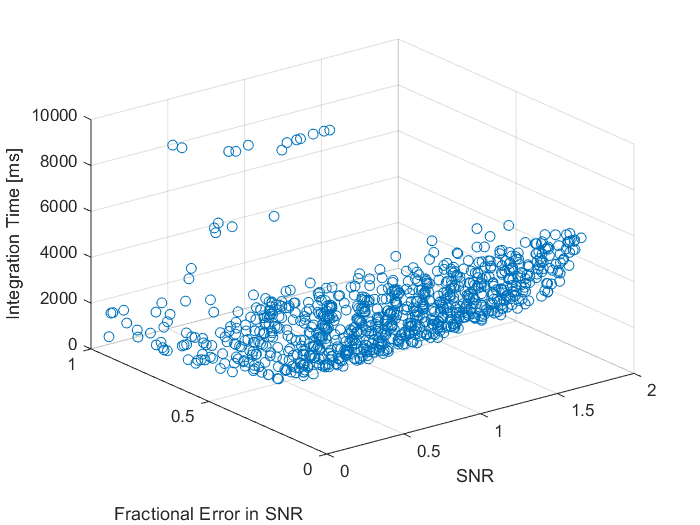

data.mean.SNR = data.mean.signal./data.mean.noise;
data.fracError.signal = data.std.signal./data.mean.signal;
data.fracError.noise = data.std.noise./data.mean.noise;
data.fracError.SNR = data.fracError.signal+abs(data.fracError.noise);
figure;
scatter3(squeeze(abs(data.mean.SNR(:))),squeeze(data.fracError.SNR(:)),squeeze(data.exp.integrationTime(:)*10^3));
xlabel('SNR');
ylabel('Fractional Error in SNR');
zlabel('Integration Time [ms]');
ylim([0 1]);

## Scattered interpolant

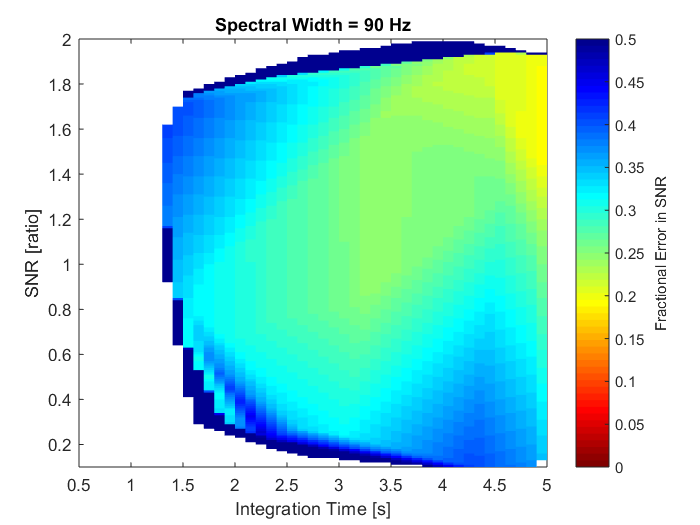

F = scatteredInterpolant(data.exp.integrationTime(:),data.mean.SNR(:),data.mean.fWidth(:),data.fracError.SNR(:),'linear','none');
xIntegrationTime = 0.5:0.1:5;
ySNR = 0.1:0.01:2;
zfWidth = 90;
[X,Y,Z]=meshgrid(xIntegrationTime,ySNR,zfWidth);
fracError = F(X,Y,Z);
figure;
h=pcolor(X,Y,fracError);
xlabel('Integration Time [s]');
ylabel('SNR [ratio]');
set(h, 'EdgeColor', 'none');
colorbar;
colormap(flipud(jet));
caxis([0 0.5]);
h = colorbar;
ylabel(h, 'Fractional Error in SNR')
title(['Spectral Width = ', num2str(zfWidth),' Hz']);

## Histograms

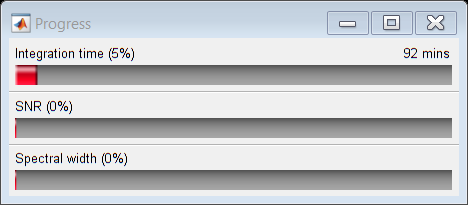

figure;
p = panel();

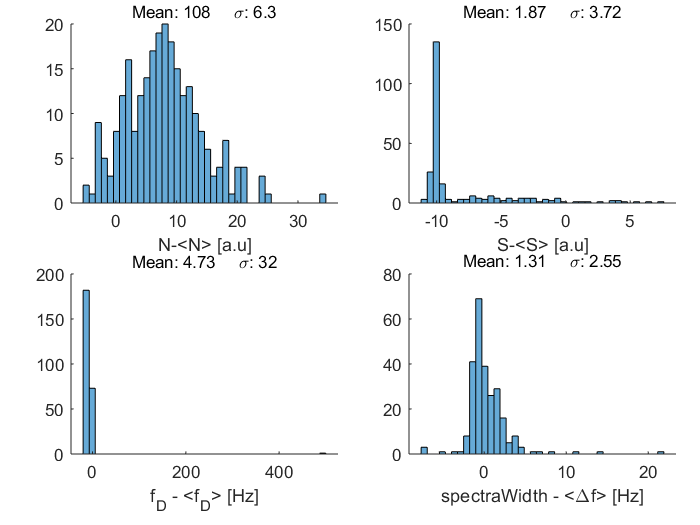

nBins=40;
p.pack(2,2);
p(1,1).select();
histogram(real(noiseDist(:))-noisePower,nBins);
xlabel('N-<N> [a.u]');
display_statistics=@(dist) title(['Mean: ',num2str(mean(real(dist(:))),3),'     \sigma: ',num2str(std(real(dist(:))),3)]);
display_statistics(noiseDist);

p(1,2).select();
histogram(real(signalDist(:))-signalPower,nBins);
xlabel('S-<S> [a.u]');
display_statistics(signalDist);

p(2,1).select();
histogram(real(dopplerShiftDist(1,:))/(2*pi)-dopplerFrequency,nBins);
xlabel('f_D - <f_D> [Hz]');
display_statistics(dopplerShiftDist/(2*pi));

p(2,2).select();
histogram(real(fWidthDist(1,:))-fWidth,nBins);
xlabel('spectraWidth - <\Deltaf> [Hz]');
display_statistics(fWidthDist);

## Step 1: Generate model ACF

% Input to generate model ACF
clear all;
dt = 0.01;               % Sample time in seconds
nSamples = 2^6;
tDecorrelation =1/30;    % Decorrelation time in D-region in seconds
% maxLag = tDecorrelation*2;
lag = (0:1:nSamples-1)'.*dt;     % lags
totalModifiedLag = fftshift(-nSamples:1:nSamples-1)'.*dt;
% lag = linspace(0,maxLag,nSamples);     % lags
A = 100;                  % Signal intensity
omegaDoppler = -2*pi*0;       % Doppler shift of frequency
N = 0;                  % Noise intensity
nEnsembles = 40;
nExperimentRuns = 256;

% Calculating the ACF
RmArray =autocorrelation_model(N,A,tDecorrelation,omegaDoppler,lag,dt);
Rm = conj(toeplitz(RmArray)');
fD = 1/tDecorrelation;
frequency = (0.5/dt)*linspace(-1,1-2/nSamples,nSamples);
Sm = N + 2*A*fD./(fD^2+4*pi^2*(frequency+omegaDoppler/(2*pi)).^2);
% Sm = Sm;

%Fitting options
inputNLR0=[0,0,0]; %N, A, wDoppler
options = optimoptions(@lsqnonlin,'Algorithm','levenberg-marquardt','MaxFunctionEvaluations',10000,'MaxIterations',2000,'Display','none');

## Step 2: Generate voltage samples that follow model ACF

B = chol(Rm,'lower');

for thisEnsemble = 1:1:nEnsembles
    X = randn(nSamples,nExperimentRuns);
    V = B*X;
    for thisExperiment = 1:1:nExperimentRuns

## Step 3: Calculate an instance of the ACF (or ACF estimator) from these voltage samples

        [S,f,moments] = get_power_spectra(V(:,thisExperiment),lag,'signal');
        SArrayCollection(:,thisExperiment) = S;
        [Sm1,f1,moments1] = get_power_spectra(RmArray,lag,'acf');
        RArrayCollection(:,thisExperiment) = moments.ACF_Array_modified;
        RmArrayCollection1(:,thisExperiment) = moments1.ACF_Array_modified;
    end
    

## Step 4:  Estimate the variance of the power spectra

    covR=cov(RArrayCollection');
    %     covRm = cov(RmArrayCollection1');
    %     D = moments1.D;
    %     covS = fftshift(D*covR*D').*dt.^2;
    %     covS1=cov(SArrayCollection');
    %     covSm = D*covRm*D';
    

## Step 5: Fitting

    varR = repmat(diag(covR),1,nExperimentRuns);
    variance = varR;
    data = RArrayCollection;
    
    chi_square = @(inputNLR) sum(abs(((autocorrelation_model(inputNLR(1),inputNLR(2),tDecorrelation,inputNLR(3),totalModifiedLag,dt)-data).^2))./variance);
    
    %   Levenberg-Marquardt fitting
    inputNLR = lsqnonlin(chi_square,inputNLR0,[],[],options);
    outputNLR(:,thisEnsemble) = inputNLR;
end
NLRm = mean(outputNLR,2);

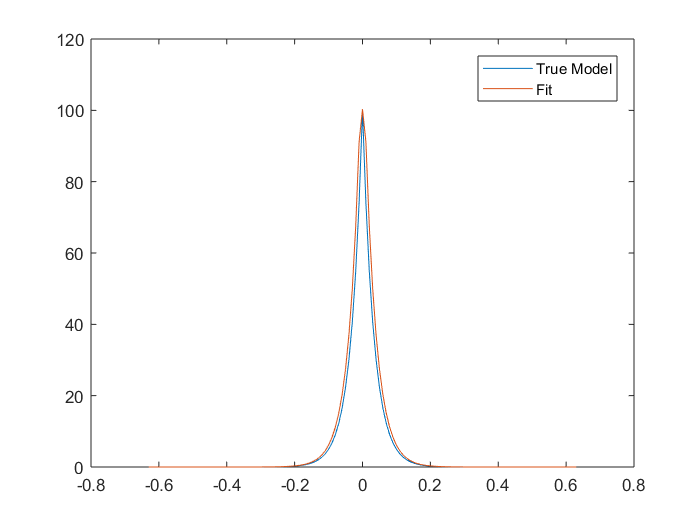

% Plotting fit vs actual model
totalLag = (-nSamples+1:1:nSamples-1)'.*dt;
figure;plot(totalLag,real(autocorrelation_model(N,A,tDecorrelation,omegaDoppler,totalLag,dt)));
hold on; plot(totalLag,real(autocorrelation_model(NLRm(1),NLRm(2),tDecorrelation,NLRm(3),totalLag,dt)));
legend('True Model','Fit');

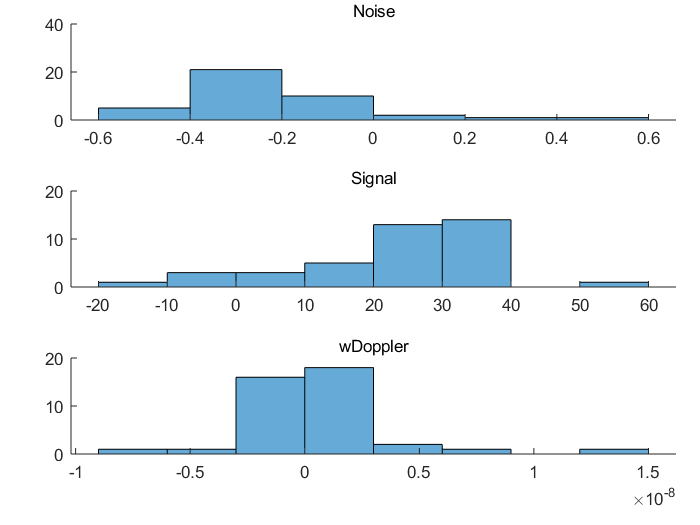

% Histograms
figure;
p = panel();
p.pack(3,1);
p(1,1).select();
histogram(outputNLR(1,:)-N);
title('Noise');
p(2,1).select();
histogram(outputNLR(2,:)-A);
title('Signal');
p(3,1).select();
histogram(outputNLR(3,:)-omegaDoppler);
title('wDoppler');

## Plot Test Bed

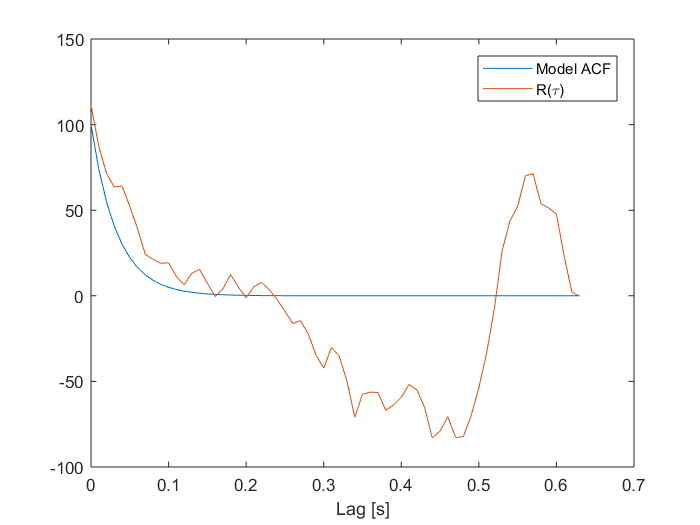

% testToeplitz = toeplitz(conj((1+1i)*(1:10))');
%
% figure;
% N = 1; %Noise intensity
% RmArray =N*double(lag==0)/dt + A.*exp(-abs(lag)./tDecorrelation).*exp(-1i*omegaDoppler.*lag);
% plot(lag,RmArray);
% hold on;
% N = 0; %Noise intensity
% RmArray =N*double(lag==0)/dt + A.*exp(-abs(lag)./tDecorrelation).*exp(-1i*omegaDoppler.*lag);
% plot(lag,RmArray);
% xlabel('lag');
% ylabel('R_m Model Autocorrelation')

figure;plot(lag,RmArray); hold on;
plot(lag,moments.ACF_Array);xlabel('Lag [s]');
legend('Model ACF','R(\tau)');

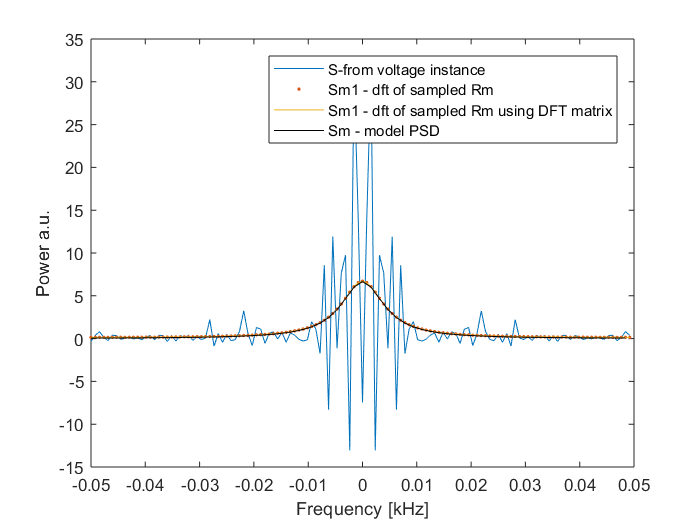



figure;
% plot(f/1000,P2); xlabel('Frequency [kHz]');
% hold on;
% plot(f/1000,fftshift(abs(S)/nSamples),'.');
% hold on;
plot(f/1000,S);
hold on;
plot(f1/1000,Sm1,'.');
hold on;
plot(f1/1000,moments1.S_DFT);
hold on;
plot(frequency/1000,Sm,'k');
xlabel('Frequency [kHz]');
ylabel('Power a.u.')

legend('S-from voltage instance','Sm1 - dft of sampled Rm','Sm1 - dft of sampled Rm using DFT matrix','Sm - model PSD');


% Plot covariance matrix
figure;semilogy(f/1000,(real(diag(covS))));

Undefined function or variable 'covS'.

xlabel('Frequency'); ylabel('Variance S');
figure;semilogy(f/1000,(real(diag(covR)))); title('var(R)');
plot(f/1000,fftshift(diag(real(covSm))));
figure;semilogy(f/1000,fftshift(real(diag(covS)))); hold on; plot(f/1000,fftshift(diag(real(covSm))));

xlabel('Frequency [kHz]');
ylabel('Variance');

figure;
imagesc(real((real(covR))));
title('cov(R)');
colormap('inferno'); colorbar;
% caxis([0 6]);


figure;
imagesc(real((real(covS1))));
title('Covariance of the spectra'); colormap('inferno'); colorbar;
% caxis([0 6]);


figure;
imagesc(real((real(covS))));
title('Covariance of the spectra'); colormap('inferno'); colorbar;

function RmArray = autocorrelation_model(N,A,tDecorrelation,omegaDoppler,lag,dt)
RmArray =N*double(lag==0)/dt + A.*exp(-abs(lag)./tDecorrelation).*exp(-1i*omegaDoppler.*lag);
end

